# Generation and manipulation of reconstructions with rBioNet

**Author(s): Ines Thiele, Ronan M. T. Fleming, Systems Biochemistry Group, LCSB, University of Luxembourg.**

**Reviewer(s): Catherine Clancy, Stefania Magnusdottir, LCSB, University of Luxembourg.**

rBioNet is a reconstruction tool that lets you assemble reconstruction in a user friendly environment. In this tutorial you shall learn how you can use this tool to either start a new reconstruction or load in an existing one, followed by, its analysis. The tool consists of 3 main parts, i.e., metabolite creator, reaction creator and reconstruction creator. The metabolite creator is used to add in metabolites and its associated information, i.e., its elemental formula, charge, identifiers (for e.g., KEGG ID, PubChem ID etc.) and other associated attributes. Alternatively, a text file containing all the necessary information in the same order as in the metabolite database can be loaded directly. The reaction creator is used to formulate reactions and as stated before a text file containing all the necessary information about the reaction abbreviation, description, formula, reversibility, confidence score, notes, references. Alternatively, a text file containing all the necessary information in the same order as in the reaction database can be loaded on to the reaction creator directly. The reconstruction creator is used to load in reactions from the reactions database and then assign GPRs (gene-protein-reaction association), subsystem, add in more information in the notes and reference section. Once you have completed your reconstruction you can look at the S-matrix, identify dead ends, look for neighboring reaction to a particular reaction and plot metabolite connectivity in the reconstruction creator with its statistics function.

 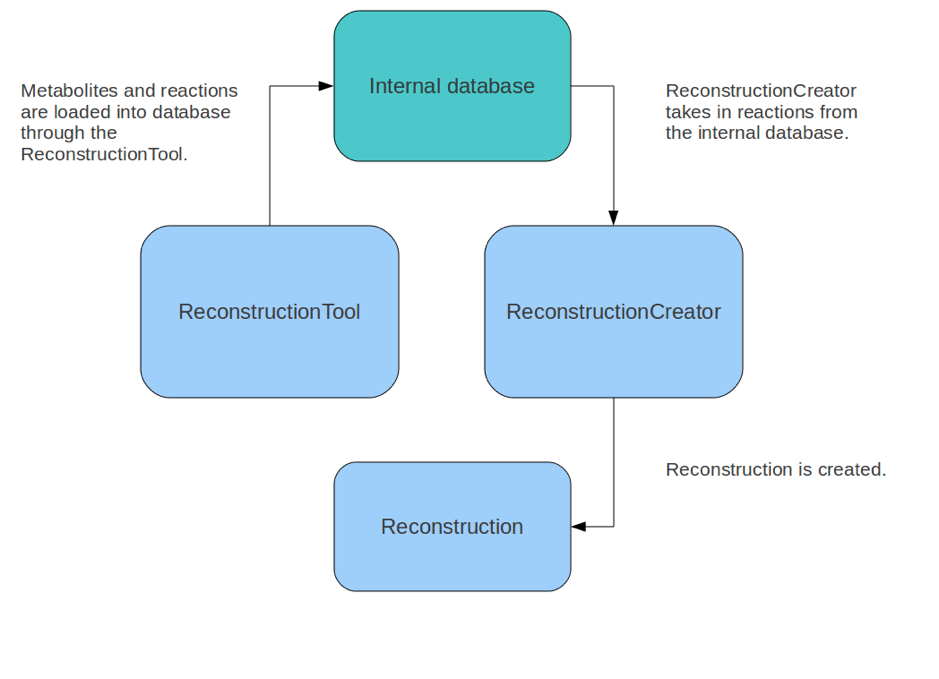

## Features of rBioNet:

***Environment to assemble reconstruction that consists of 3 parts***

- Metabolite creator

- Reaction creator

- Reconstruction creator

***Metabolite creator***

- Associated with a metabolite database.

- Used to create a new metabolite in one of three possible ways:

- Uploading from a text file that contains all the information in the same order as in the database.

- Manually filling in all the information.

- Loading from other COBRA reconstructions.

- Checks for duplicate entries.

- Checks the metabolite abbreviation and charged formula.

- Metabolites are organism and compartment independent.

***Reaction creator ***

- Associated with a reaction database.

- Methods to create a reaction is same as for metabolites.

- Reactions contain metabolites pre-existing in the metabolite database.

- Checks for duplicate entries, mass and charge balance.

- Reactions are organism independent but compartment specific. The same reaction can occur in different compartments.

- Either start from scratch or load pre-existing reconstruction.

- Primarily used to assign GPRs.

- Also to add notes, subsystem etc.

***Add-ons ***

- Reconstruction analyzer.

- Checks for dead-end metabolites.

- Provides suggestions for exchange reactions.

- S-matrix visualization. 

- Neighbor Reactions & Metabolite connectivity.

## EQUIPMENT SETUP

## **Initialize the COBRA Toolbox.**

Initialize The Cobra Toolbox using the `initCobraToolbox` function.

initCobraToolbox(false) % false, as we don't want to update



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

global CBTDIR; %Get the folder of the toolbox.

## **Setting the **optimization** solver.**

This tutorial will be run with a `'glpk``'` package, which is a linear programming ('`LP'`) solver. The `'glpk``'` package does not require additional instalation and configuration.

solverName='glpk';
solverType='LP'; 
changeCobraSolver(solverName,solverType,1);

However, for the analysis of large models, such as Recon 3, it is not recommended to use the `'glpk``'` package but rather an industrial strength solver, such as the `'gurobi'` package.

A solver package may offer different types of optimization programmes to solve a problem. The above example used a LP optimization, other types of optimization programmes include; mixed-integer linear programming ('`MILP`'), quadratic programming ('`QP`'), and mixed-integer quadratic programming ('`MIQP`').

warning off MATLAB:subscripting:noSubscriptsSpecified

if usejava('desktop') % This line of code is to avoid execution of this turorial in non gui-environments    

## Steps to load and initiate the Reconstruction Tool

Start up: rBioNet needs a pre-existing database to start up. Stored in the rBioNet is a database. The database consists of the ten reactions of the glycolysis pathway. Hence, you will see the glycolysis reactions in the reaction creator window, the metabolites participating in these reactions in the metabolite creator window.

**1.** Initiate rBioNet by linking the database files.

- For the tutorial, we will create a file "rBioNetSettingsDB.mat" that contains the paths to the tutorial reaction, metabolite, and compartment database files.

%Get the path of the tutorial to store the rBioNet Databases in this folder.
%If you want to use another folder just change the pathes.
tutorialPath = fileparts(which('tutorial_rBioNet'));
comp_path = [tutorialPath filesep 'tutorial_compartments.mat'];
met_path = [tutorialPath filesep 'tutorial_metabolites.mat'];
rxn_path = [tutorialPath filesep 'tutorial_reactions.mat'];
save([tutorialPath filesep 'rBioNetSettingsDB.mat'],...
    'comp_path', 'met_path', 'rxn_path')

- Note there are three .mat files, corresponding to the reaction database, metabolite database, and the compartment database.

rBioNetSettings

Click on the change tab for reactions and locate to the tutorial_reactions.mat file, which is provided to you in the rBioNet tutorial folder.

*Reactions-> Change-> tutorial_reactions.mat->save*

Click on the change tab under metabolites and locate to the tutorial_metabolites.mat file, which is provided to you in the rBioNet tutorial folder.

 *Metabolites->Change-> tutorial_metabolites.mat->save*

Click on the change tab under compartment and locate to the tutorial_compartments.mat file, which is provided to you in the rBioNet tutorial folder. 

*Compartment->Change-> tutorial_compartments.mat -> save*

This is the pre-existing database with glycolysis reactions and you saved it as your current database. You can modify it or remove the reactions as per your requirements. 

## Open and nagivating in rBioNet

Let's open the rBioNet tool:

ReconstructionTool 

A window appears called the 'Reaction and Metabolite Editor'. 

Click on the *Reaction View Table* and then S*how All*, which shall show all the glycolysis reactions.

Reaction view table: *Reaction creator -> Refresh/Show All*

 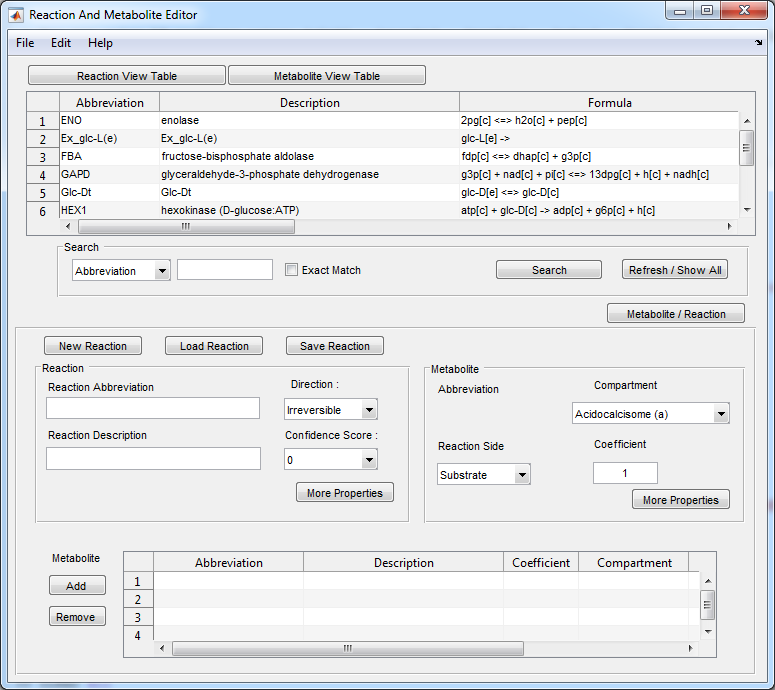

Click on the *Metabolite View Table* and then S*how All*, which shall let you see all the glycolysis metabolites

Metabolite view table: *Metabolite creator -> Refresh/Show All*

 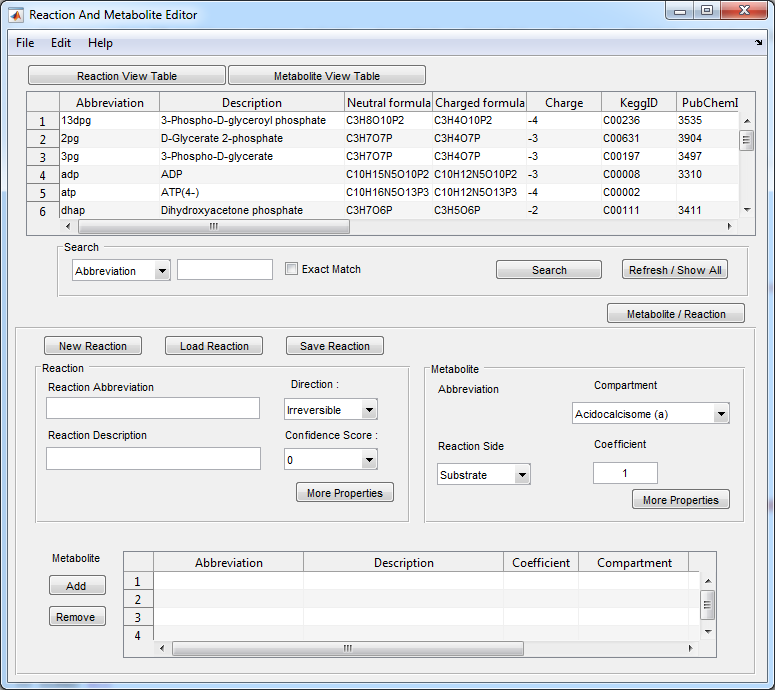

To visualize the 'Reconstruction Creator' window go to File and Open the model creator. 

*File -> Open Model Creator -> Reconstruction Creator*

 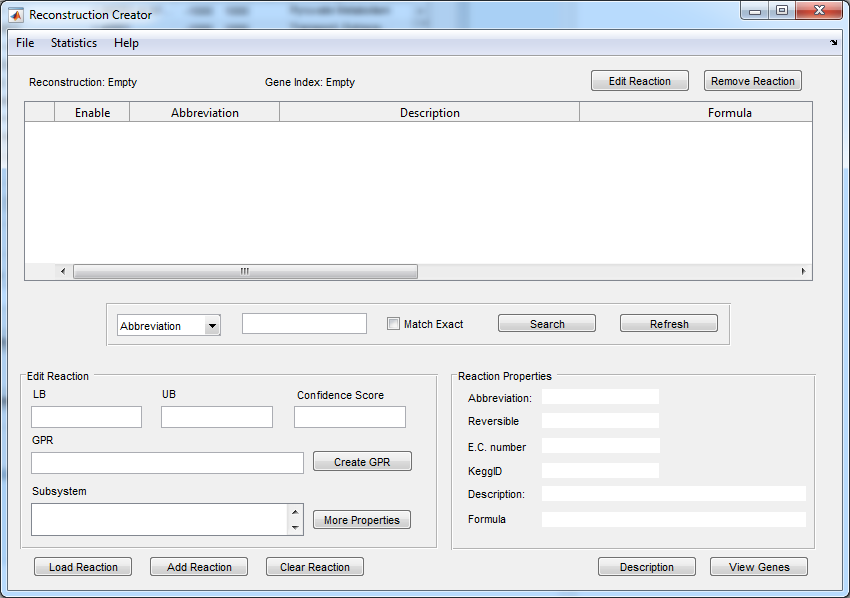

**Load in the *****E.coli***** core model into the reconstruction creator **

In the Reconstruction Creator do as follows:

*File -> open model -> complete reconstruction -> select the E. coli core model provided in the tutorial folder (tutorial_Ecoli_core_model.mat) -> click yes on the reconstruction description bar –> click no on the load gene index bar.*

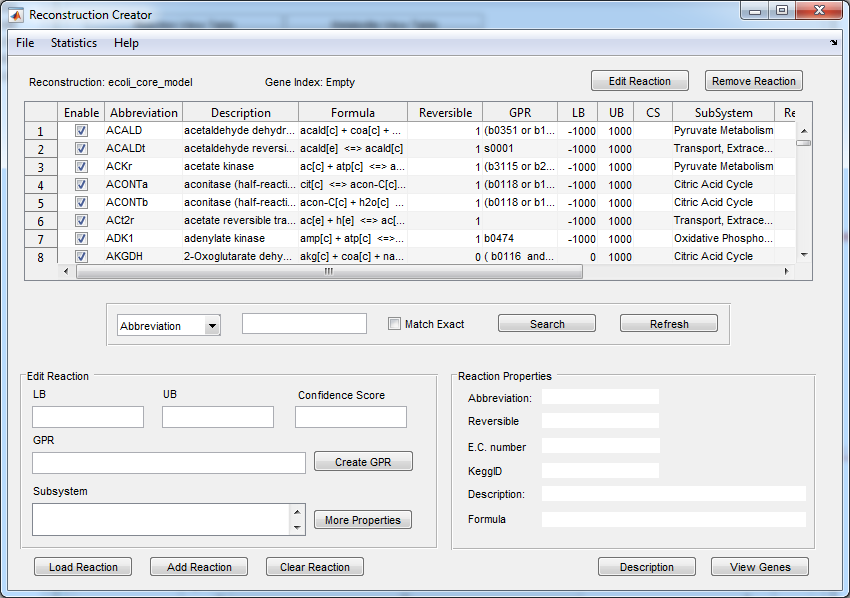

Now, we see the content of the *E. coli*_core model in the reconstruction creator.

On the reconstruction creator, click on S*tatistics -> Reconstruction analyzer. *A window called the 'Reconstruction Analyzer*' *appears and is used to visualize the S-matrix and identifies dead end metabolites.

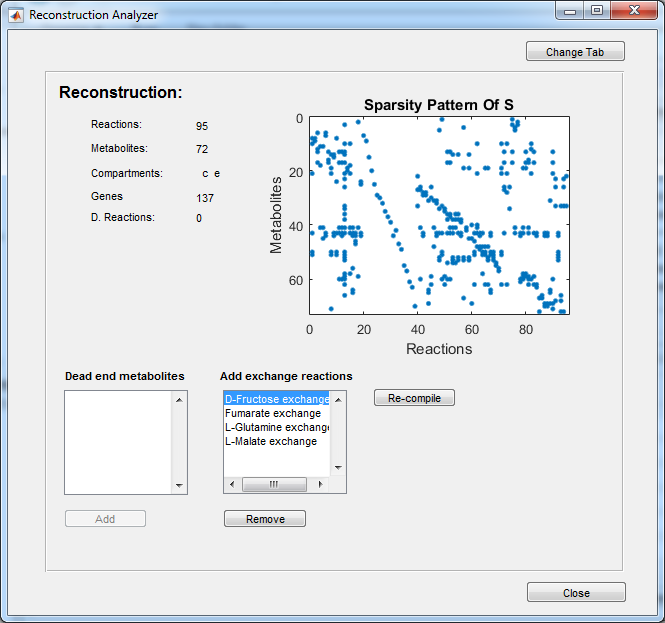

## Adding new metabolites

**Manually adding a new metabolite**

Go to the Reaction and Metabolite Editor window and click on the Metabolite/Reaction tab to switch to the New/Load/Save Metabolite view. 

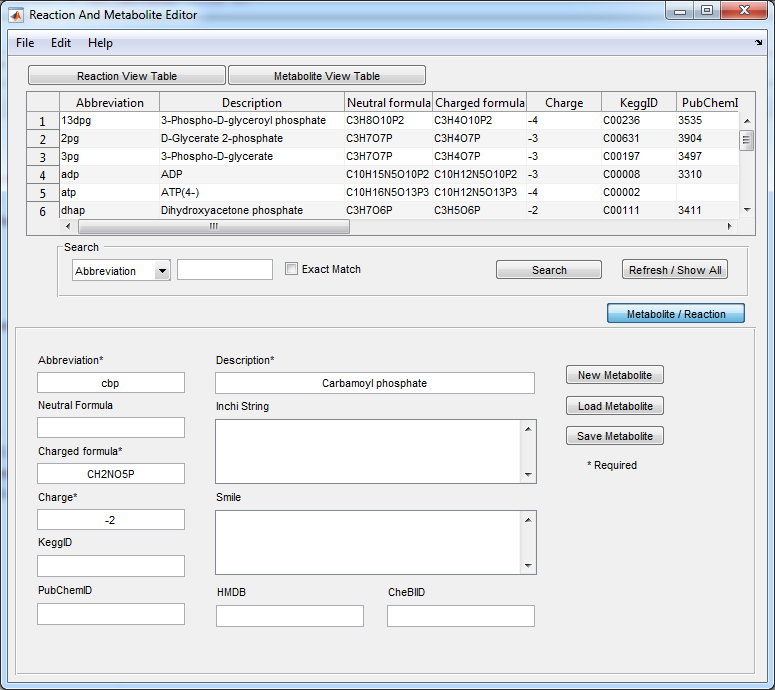

- Enter the required information for a new metabolite, including: abbreviation (cbp), description (Carbamoyl phosphate), charged formula (CH2NO5P), and charge (-2). 

- Then click Save Metabolite.

**Adding metabolites from a text file**

Alternatively, load a text file directly into the Reaction and Metabolite Editor.

*Go to file -> add text file -> with metabolite -> *select the file tutorial_ureacycle_mets.txt *(provided in the tutorial folder)*  

Click yes on each window that appears.

- When you are using this approach to create your reconstruction, make sure that all the information is **absolutely correct** and thoroughly checked before you make the addition.

 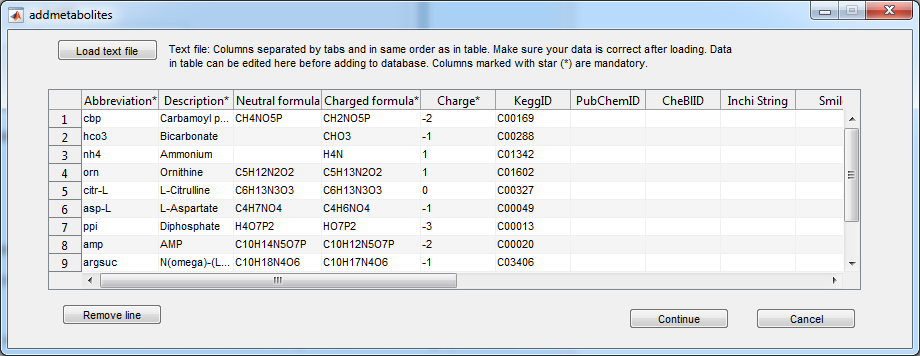

## Adding new reaction

**Manually adding reactions**

Go to the Reaction and Metabolite Editor window and click on the Metabolite/Reaction tab to switch to the New/Load/Save Reaction view. 

Then, click New Reaction and enter the reaction information including: the reaction abbreviation (ARGN), description (arginase), direction (Irreversible), and confidence score (4). Click on More Properties to add additional information (Notes, References, EC Number, KeggID).

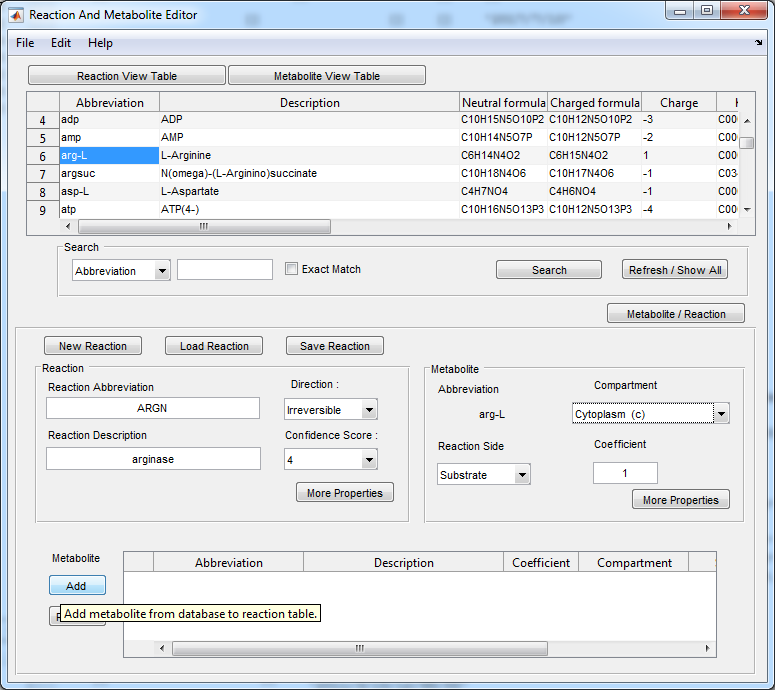

Next go the "Metabolite View Table" and select a metabolite belonging to the reaction. 

Enter the metabolite's coefficient, compartment and reaction side (substrate or product).

- Metabolite: arg-L, Compartment: Cytoplasm (c), Reaction Side: Substrate, Coefficient: 1. -> Click Add to add the metabolite to the reaction.

- Metabolite: h2o, Compartment: Cytoplasm (c), Reaction Side: Substrate, Coefficient: 1. -> Add.

- Metabolite: orn, Compartment: Cytoplasm (c), Reaction Side: Product, Coefficient: 1. -> Add.

- Metabolite: urea, Compartment: Cytoplasm (c), Reaction Side: Product, Coefficient: 1. -> Add.

Save the reaction.

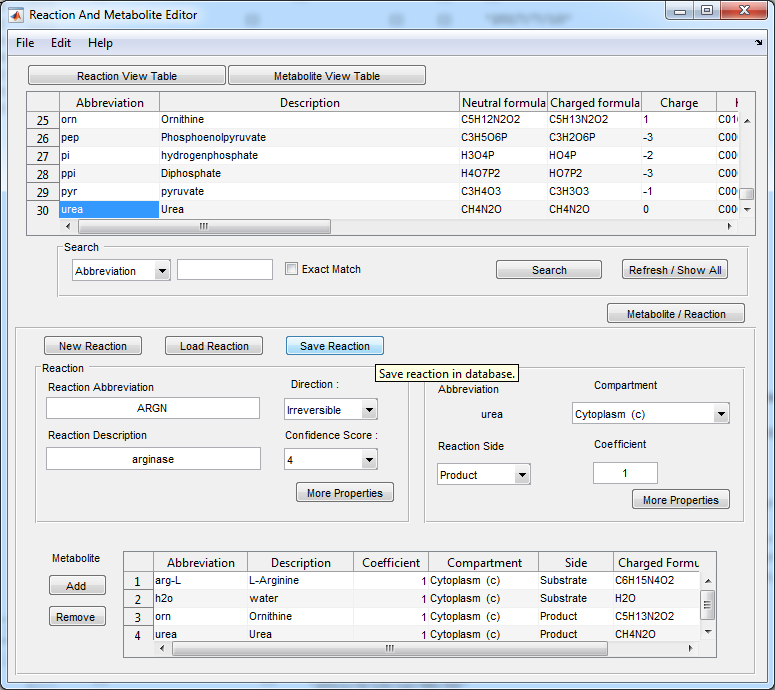

- For the assignment of GPRs to reaction ('Create GPR') please refer to the next section.

Now, the tool checks for elemental and charge balancing, and provides a warning if there is an error.

If everything is correct in the follow up window, click yes to save your reaction.

**Adding reactions from a text file**

Alternatively, load a text file directly into the Reaction and Metabolite Editor.

*Go to file -> add text file -> with reactions -> *select the file* tutorial_ureacycle_rxns.txt* (provided in the tutorial folder)  

Click on Perform Check to make sure all reactions are mass and charge balanced.

- When you are using this approach to create your reconstruction, make sure that all the information is **absolutely correct** and thoroughly checked before you make the addition.

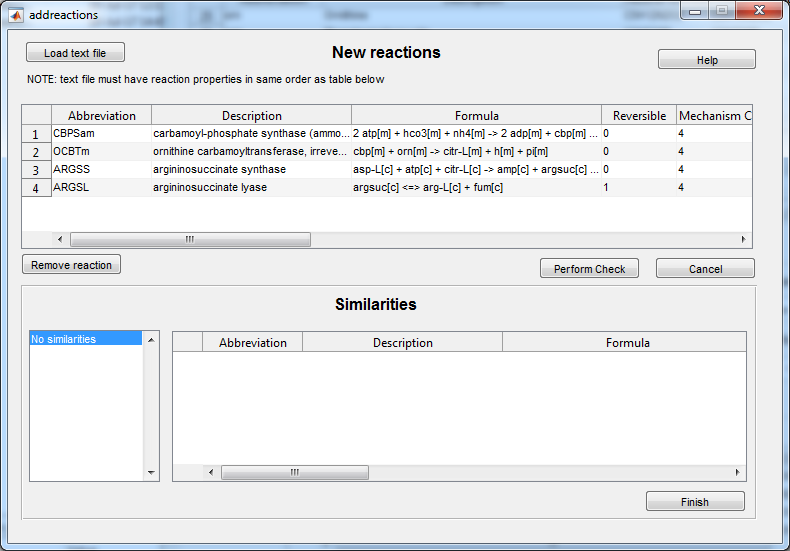

## Assigning GPRs to the reactions

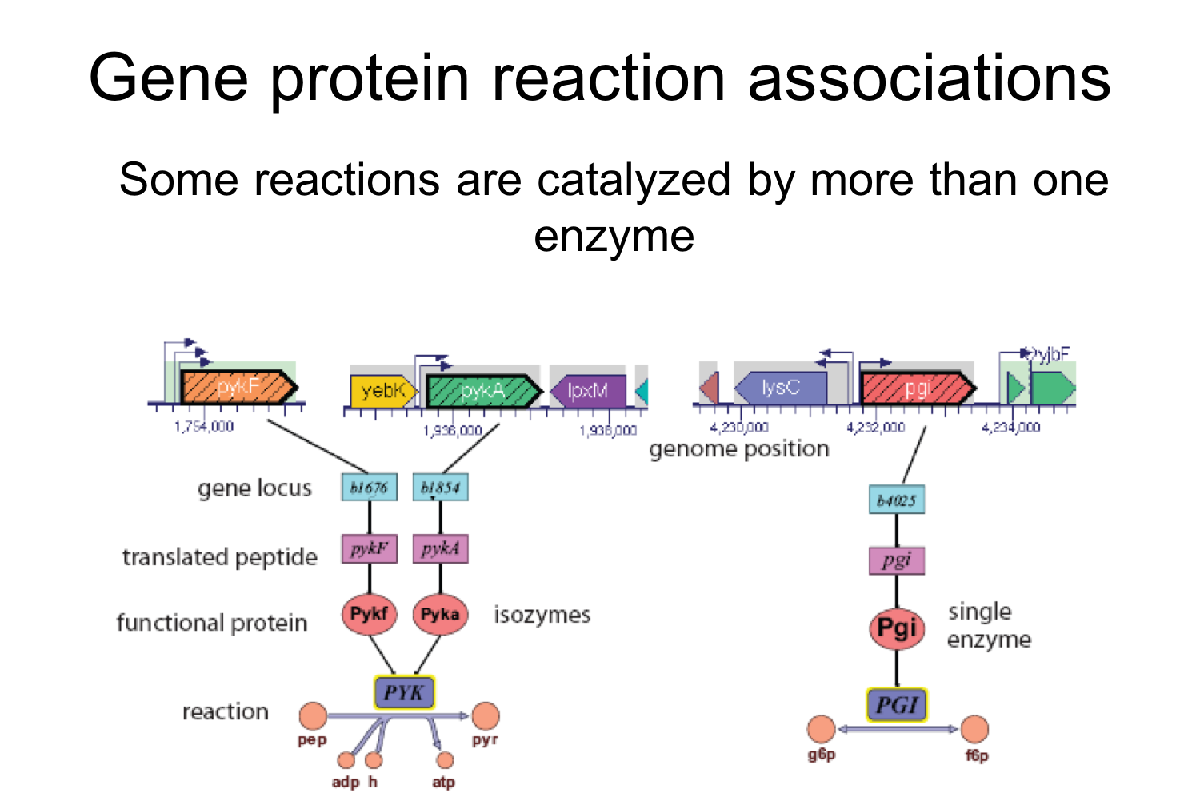

- On the Reaction and Metabolite Editor go to File -> Open Model Creator

- On the Reconstruction creator window go to File -> Click on 'Load gene index' -> select the file* tutorial_ureacycle_genes.txt* (provided in the tutorial folder) 

- Add a reaction from the reaction database to the model by clicking on 'Load reaction'

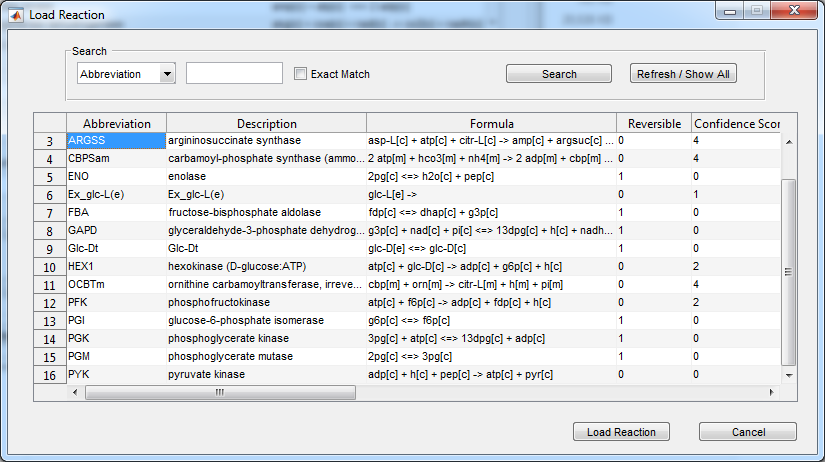

-  Select a reaction (ARGSS) that you want to assign a GPR, and then click 'Load reaction'.

- Click on Create GPR 

- Click on genes you want to assign -> click add genes.

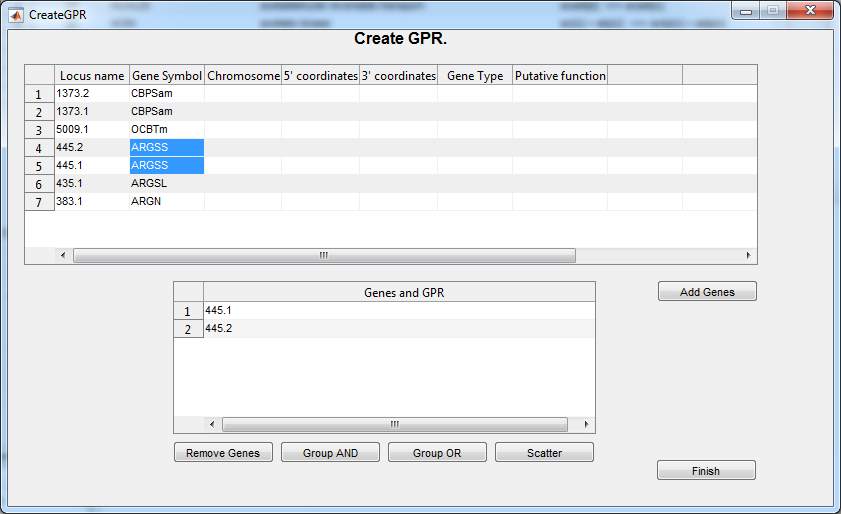 

**Add an AND/OR rule to a group of genes:** Click 'Group AND' for groups selected genes with and, or click 'Group OR' for groups selected genes with or.

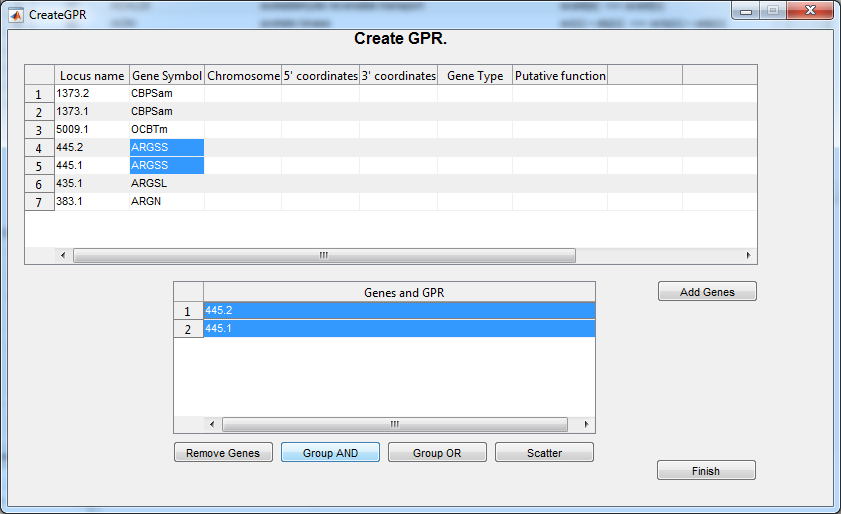

-  Once the GPR has been configured correctly with AND/OR rules, click Finish.

Once the GPR has been assigned and other edits done (for e.g., addition of subsystem, further notes and references), click the Add Reaction button in the Reconstruction Creator. 

- If editing an existing reaction, a window appears asking if you want to replace the current reaction -> click yes. 

Now you should be able to see the new edited (i.e., GPR associated) reaction in the list of reactions on the reconstruction creator. 

Once you have finished with all the reactions, go to File -> Save -> As Reconstruction Model. 

If you made errors while adding metabolites or reactions manually, you can load the reaction or metabolite database .mat files directly into the MATLAB workspace and delete/ edit it in the variable editor in the MATLAB and save it. This shall be your new database from now on. 

**Make sure that you never make errors while filling in the information in the database.** 

## Clean-up

Remove "rBioNetSettingsDB.mat" file from the tutorial directory.

fclose all;% close all open windows
delete([CBTDIR filesep 'tutorials' filesep 'rBioNet' filesep 'rBioNetSettingsDB.mat'])

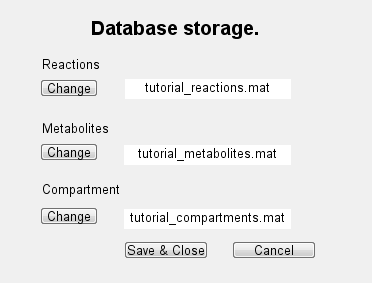

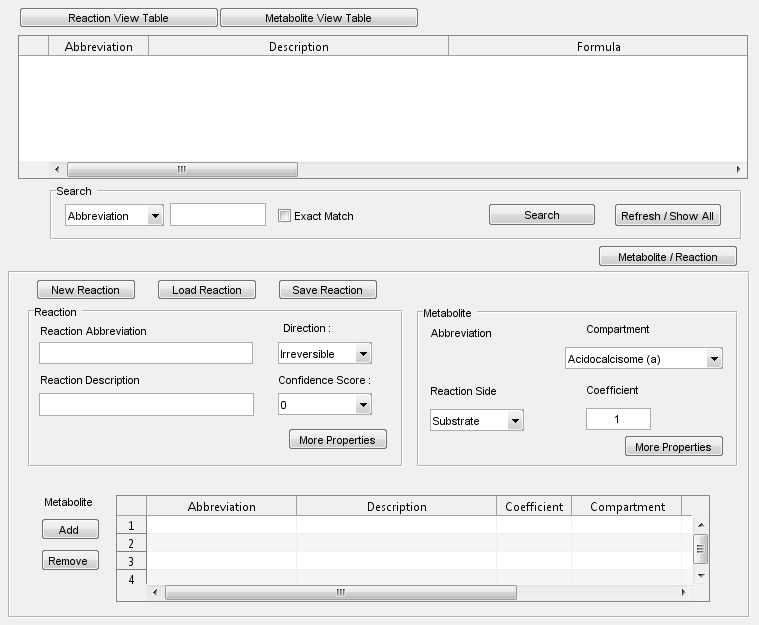

end

## Reference

[1] Thorleifsson SG, Thiele I. Bioinformatics. 2011 Jul 15;27(14):2009-10. 